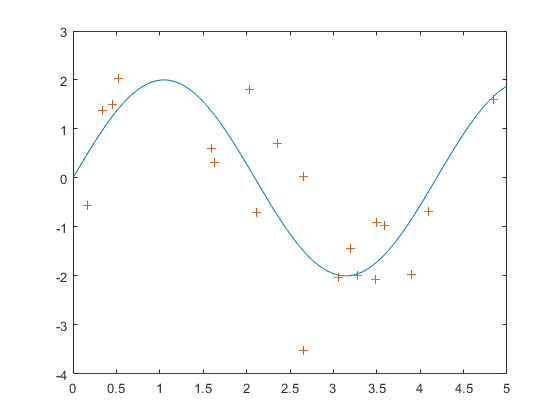

%Create sin function f(x) = 2sin(1.5x).
x = linspace(0,5);
y = 2*sin(1.5*x);
figure;
plot(x,y);
hold on;

%Randomly select 20 points along x. Do so twice: once for training set and once for validation set.
xrandt = 5.*rand(20,1);
% rand: (0,1)  5.*rand: (0,5) 
xrandv = 5.*rand(20,1);

%Calculate sin values at random x points, add normally distributed noises
yrandt = 2*sin(1.5.*xrandt) + randn(20,1); 
yrandv = 2*sin(1.5.*xrandv) + randn(20,1);
scatter(xrandt,yrandt,"+");
hold off;

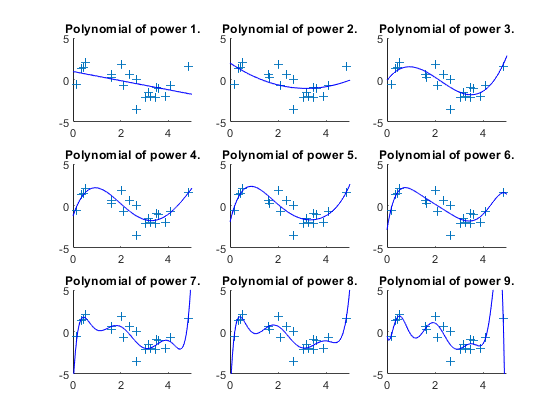

%Create figure of Data and fitted polynomials. To see clearly, break it into 9 subplots.
%For each subplot, plot training data set and fitted polynomial.
for R = 1:9
subplot(3,3,R);
hold on;
xlim([0,5]);
ylim([-5,5]);
title(sprintf('Polynomial of power %d.', R));

%Plot training data.
scatter(xrandt,yrandt, "+");

%Create polynomial function that tries to fit training data.
poly = polyfit(xrandt,yrandt,R);
%Calculate y value at each x value, using polynomial function.
yfitted = polyval(poly,x);
plot(x, yfitted, 'b');
hold off;


trainError(R,:) = yrandt - polyval(poly, xrandt);
valError(R,:) = yrandv - polyval(poly,xrandv);
trainSSE(R) = sum(trainError(R,:).^2);
valSSE(R) = sum(valError(R,:).^2);

end

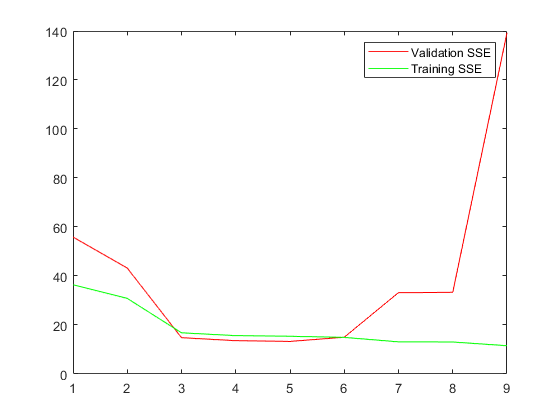

%Plot figure of Error vs. polynomial order
figure
plot(1:9,valSSE,'r',1:9,trainSSE,'g');
legend('Validation SSE','Training SSE');